clear;

% Independent Variables
NumOfParticles = 10000;
NumOfPatterns = 100;
NumOfGenerations = 1000;

% Dependent Variables
PatternSize = NumOfParticles/NumOfPatterns;
Pattern = zeros(PatternSize, NumOfPatterns);
CentrePixel = ceil(PatternSize/2);

for i = 1:1:NumOfPatterns
    Pattern(:,i) = rand(PatternSize,1);
    Pattern(:,i) = ElectricField(Pattern(:,i));
end

T = TransmissionMatrix(PatternSize);
A = T * Pattern;
I = abs(A).^2;
F = I(CentrePixel,:)

F =     0.1607    1.5833    2.0114   13.9131   30.1367    3.5035    0.2542    1.9987    4.8602    8.1327    3.8776    0.3986    9.6909    3.6176    5.5871    5.9633    8.4530    0.7566    2.8459    0.5419    8.2156   12.0305    4.8314    3.3957    0.2460    0.0409    2.3495    0.4145    7.3093    1.1319    2.4455    4.7825    5.4603    1.6003    1.9641    5.5475    5.9734    7.0588   12.0812    4.2448    8.9439   10.2986    9.3442    8.9757    0.7839    3.4318   11.1774    0.9830    1.1352    0.1476



MutationRate = 0.1;
BestFits = zeros(NumOfGenerations, 1);
BestPattern = zeros(PatternSize, NumOfGenerations);

tic
for i = 1:1:NumOfGenerations
    NumOfPatterns = length(Pattern(1,:));
    % Since Number Of Patterns Starts off as 10 but then 100 child patterns
    % are made, the number of patterns has to be updated

    Fitness = F;
    [bestFitness, bestIndex] = max(Fitness);
    BestFits(i) = bestFitness;
    BestPattern(:,i) = Pattern(:, bestIndex);


    ChanceOfSelection = Fitness / sum(Fitness); % Creates weighted probability to use in selection
    IndexSelection = randsample(1:NumOfPatterns, NumOfParticles, true, ChanceOfSelection);
    PatternSelection = Pattern(:,IndexSelection);

    ChildPatterns = zeros(PatternSize, NumOfParticles);
    for j = 1:1:NumOfParticles
        Parent1 = PatternSelection(:,j);
        Parent2 = PatternSelection(:,randi(NumOfParticles));
        crossPoint = randi(PatternSize);
    
        % Child takes genes from each parent up to the crossover point
        child = [Parent1(1:crossPoint); Parent2(crossPoint+1:end)];
        ChildPatterns(:,j) = child;
    end
    
    for i = 1:NumOfParticles
        if rand(1) < MutationRate
            mutatedPattern = ChildPatterns(:, i);
            mutationIndex = randi(PatternSize);
            mutatedPattern(mutationIndex) = ElectricField(rand(1));
            ChildPatterns(:, i) = mutatedPattern;
        end
    end

    Pattern = ChildPatterns;
    
    % Evaluate the new population
    A = T * Pattern;
    I = abs(A).^2;
    
    F = I(CentrePixel, :);

end
toc

Elapsed time is 90.713072 seconds.



bestFitness = max(BestFits)

bestFitness = 363.8535


disp('Best pattern:');

Best pattern:


disp(BestPattern(:,NumOfGenerations));

  -0.5878 - 0.8090i
   0.2036 + 0.9790i
  -0.2802 - 0.9599i
   0.3383 + 0.9410i
   0.0782 - 0.9969i
  -0.1836 + 0.9830i
   0.2441 + 0.9698i
   0.1703 - 0.9854i
  -0.2636 - 0.9646i
   0.2209 + 0.9753i
   0.1217 - 0.9926i
  -0.0791 - 0.9969i
   0.2210 + 0.9753i
   0.1984 + 0.9801i
   0.0728 + 0.9973i
   0.3615 - 0.9324i
  -0.1830 - 0.9831i
  -0.3264 - 0.9452i
  -0.2985 - 0.9544i
   0.4773 + 0.8787i
  -0.0056 - 1.0000i
   0.1581 + 0.9874i
   0.7058 + 0.7084i
   0.1689 - 0.9856i
  -0.3485 - 0.9373i
  -0.0389 + 0.9992i
   0.1606 + 0.9870i
   0.4237 + 0.9058i
   0.1936 + 0.9811i
   0.3356 + 0.9420i
  -0.2522 - 0.9677i
   0.4948 - 0.8690i
  -0.0599 - 0.9982i
  -0.4081 - 0.9129i
   0.1457 + 0.9893i
   0.2254 + 0.9743i
  -0.3430 - 0.9393i
   0.3545 + 0.9351i
   0.1559 + 0.9878i
  -0.2546 + 0.9671i
  -0.1297 - 0.9916i
  -0.3860 - 0.9225i
  -0.1374 - 0.9905i
   0.0140 + 0.9999i
   0.1521 + 0.9884i
   0.2072 + 0.9783i
  -0.6134 - 0.7898i
   0.0899 - 0.9959i
  -0.2846 + 0.9586i
   0.0396 + 0.9992i


disp(['Best Fitness: ' num2str(bestFitness)]);

Best Fitness: 363.8535


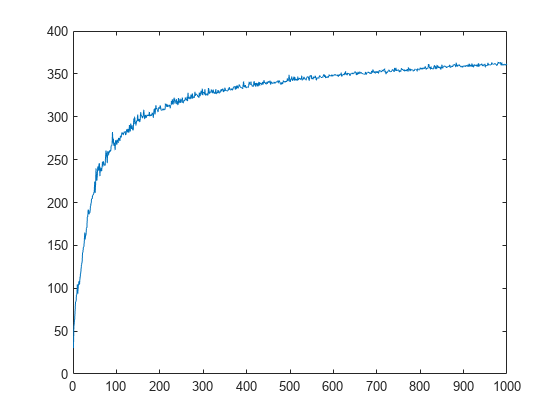


generations = 1:1:NumOfGenerations;

plot(generations, BestFits)

%heatmap(abs(Pattern))
%BestPattern(:,1)
figure;

figure;


videoFileName = 'C:\Users\maxxm\OneDrive\Loughborough Year 2\Semester 2\animated_heatmap.mp4';
videoObj = VideoWriter(videoFileName, 'MPEG-4');
videoObj.FrameRate = 20;  
open(videoObj);
colormap('jet');

for i = 1:1:4%100%NumOfGenerations

    heatmap(real(BestPattern(:, i)));
    clim([0, 1]);
    title(sprintf('Generation %d', i));
    colormap jet;
    pause(0.1);
    frame = getframe(gcf);
    writeVideo(videoObj, frame);
    clf;
end
close(videoObj);

disp(['The animated graph has been saved as "' videoFileName '".']);

The animated graph has been saved as "C:\Users\maxxm\OneDrive\Loughborough Year 2\Semester 2\animated_heatmap.mp4".


function E = ElectricField(Pattern)
    E = exp(2*pi*1i*Pattern);
end

function T = TransmissionMatrix(N)
    T = zeros(N,N);
    for i = 1:1:N
        for j = 1:1:N
            a = normrnd(0, 0.5);
            b = normrnd(0, 0.5);
            T(i,j) = (a + i*b)/N;
        end
    end
end
    
function x = sigmoid(z)
    x = 1 ./ (1 + exp(-z));
end